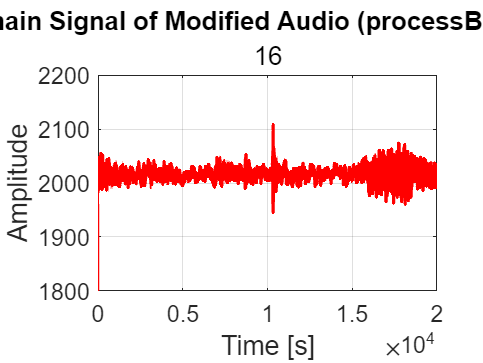

% Read the binary data (ensure correct data type, e.g., 'float' instead of 'uint16')
fid = fopen('adc_buffer_enable.bin');
data = fread(fid, inf, 'uint16'); 
fclose(fid);

% Remove DC offset by subtracting the mean
%data = data - mean(data);

% Plot the signal with labels and title
figure;
plot(data, 'r', 'linewidth', 2);  % Removed 'filled' for a clean line plot
set(gca, 'FontSize', 14);
ylim([1800 2200])
grid on;
xlabel('Time [s]', 'FontSize', 16);  % Added X-axis label
ylabel('Amplitude', 'FontSize', 16);     % Added Y-axis label
title('Time Domain Signal of Modified Audio (processBuffer Enabled)', 16);